# Compile Figures for Upper Kuparuk River Basin, Alaska

%%%%%%
%Script for compiling the figure generator
%%%%%%

clear all
close all


%What is your project name?
ProjFolder = 'figures/';

%What is the original data?
originaldata = {'UK_synthesized_data.txt'};

%do you want the figure saved?
printfig  = true;

%Where do you want to save files?
workdirfigures = '~/Documents/git_research/Permafrost_ERRA/Permafrost_ERRA/datERRA/UK_years/';

%Where is your data?
workdir = '~/Documents/git_Research/Permafrost_ERRA/Permafrost_ERRA/datERRA/UK_years';




%Set directories
workdirfig_ = {workdirfigures, ProjFolder};
workdirfig=char(strcat(workdirfig_(1),workdirfig_(2)));
if ~exist(workdirfig, 'dir')
    cd(workdirfigures)
    mkdir(ProjFolder)
end
cd(workdir)

Lets plot the results

I know the units of Q, what should the units of P be? Rainfall is at units of mm, but is that per second? The ReadMe file says precipitation is recorded hourly and nothing more. The data file says units of [mm] recorded every hour, so is it per hour? Also it says its resolution is 0.1 mm per tip. What does per tip mean?

Catchment Size of Upper Kuparuk Basin at Gauge Site is 142km^2.

From Kane:

"2007 was a relatively dry year, although all three years were below the average rainfall (222 mm). The main storage mechanism for the Upper Kuparuk is the active layer. While positive storage followed immediately after snowmelt, relative storage went from positive to negative during the summer and remained negative for the remainder of the summer as ET + Q exceeded P. The timing of this transition was later for those years with greater rainfall. Note that a large tundra wildfire in 2007 northwest of the Upper Kuparuk burned from early summer into early winter, and was the largest documented fire on the North Slope of Alaska. 

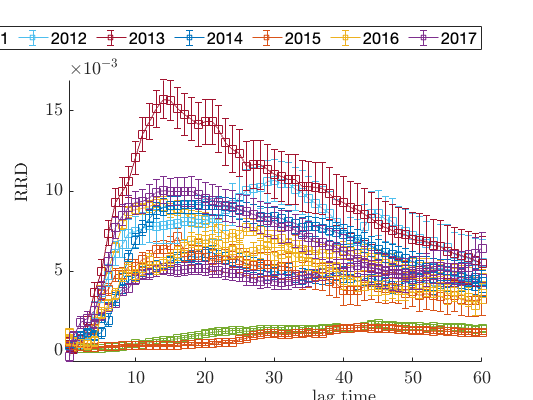


% % %Plot time with discharge and precipitation. This function will change
% % %depending on data format. Please change this function accordingly
% % origdat=char(strcat(originaldata(1)));
% % f1 = figtQP_plot_UK(origdat,workdir,workdirfig,printfig)

%Plot P and Q as scatter. We use data from ERRA so this is standardized
% f2 = figPQ_scatter(workdir,workdirfig,printfig)

%Plot ERRA time with real discharge, predicted discharge, and its residual
% str = {'1hr_simple_2003_Qcomp.txt'};
% filename=char(strcat(str(1)));
% f3 = figtQQp_plot_years(filename,workdir,workdirfig,printfig,1)

%Plot lagtime with RRD

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%FIGURES%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%




% prepare formating options
HA = {'HorizontalAlignment','left','center','right'};
VA = {'VerticalAlignment','bottom','middle','top'};
UN = {'Units','Normalized','Inches'};
TX = {'Interpreter','Latex'};
TL = {'TickLabelInterpreter','Latex'};
LW = {'LineWidth',1,1.25,1.5,2};
FS = {'FontSize',10,15,18,21,24};
MS = {'MarkerSize',6,8,12};
LS = {'LineStyle','-','--','-.',':'};
% LC = {'Color',color};


%Plotting profiles
axh = 5;
axw = 1.5*axh;
ahs = 0.15;
avs = 0.15;
axb = 0.7;
axt = 0.5;
axl = 1.0;
axr = 0.5;
cbh = axh; cbw = 0.2; ht = 0.05;
fh = axb + 1*axh + 1*avs + 1*ht + axt ;
fw = axl  + axw + ahs + cbw + axr;


% %set figure page
f1 = figure;
% set(f1,'Units','Inches','Position',[0.7 12 fw fh]);
% set(f1,'PaperPosition',[0 0 fw*2.2 fh*2.2],'PaperSize',[fw fh]);
% set(f1,'Color','w','InvertHardcopy','off', 'MenuBar','none');
% set(f1,'Resize','off','Toolbar','none');
% ax = axes('Units','Inches','position',[axl axb axw axh]);

years = 2007:2017;
maxRRD = zeros(size(years));
maxRRDlgt = zeros(size(years));
% RRD = zeros(numel(years),2000);
% se  = zeros(numel(years),2000);
% lagt = zeros(numel(years),2000);

for jj = 1:numel(years) 
str = {'1hr_simple_',mat2str(years(jj)),'_RRD.txt'};
filename=char(strcat(str(1),str(2),str(3)));
[maxRRD(jj),maxRRDlgt(jj),RRD(:,jj),se(:,jj),lagt(:,jj)] = figtRRD_plot_years(filename,workdir,workdirfig,printfig);
end


set(gca,'XLim',[min(min(lagt)),max(max(lagt))],'Ylim',[min(min([RRD-se])), max(max([RRD+se]))],TL{:},FS{[1,4]});

%set axis
xlabel('lag time',TX{:},FS{[1,4]},UN{[1,3]},'Position',[axw/2+ahs/2,-axb/2]);
ylabel('RRD',TX{:},FS{[1,4]},UN{[1,3]},'Position',[-axl/2,axh/2]);
legend(num2str(years.'), 'Location', 'northoutside', 'Orientation', 'horizontal');
%Save figure
if printfig
  cd(workdirfig);
  % set printing options
  str       = {'ltRRD' };
  format    = '-dpng';
  resl      = '-r200';
  rend      = '-opengl';
  figname   = char(strcat(str(1)));
  print(f1,format,resl,rend,figname,'-loose');
end

# Plot the lag hour with each year

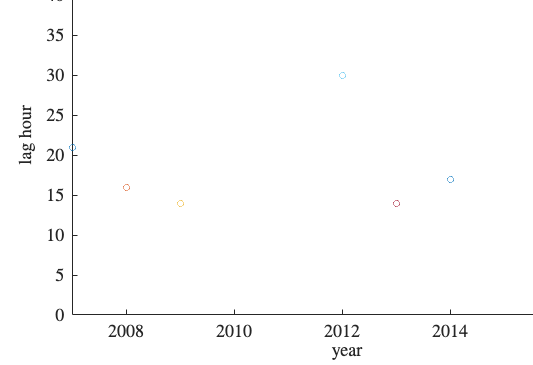

%set figure page
f2 = figure;
set(f2,'Units','Inches','Position',[0.7 12 fw fh]);
set(f2,'PaperPosition',[0 0 fw*2.2 fh*2.2],'PaperSize',[fw fh]);
set(f2,'Color','w','InvertHardcopy','off', 'MenuBar','none');
set(f2,'Resize','off','Toolbar','none');
ax = axes('Units','Inches','position',[axl axb axw axh]);
hold on
for jj = 1:numel(years)
    plot(years(jj),maxRRDlgt(jj),'o')
end
set(gca,'XLim',[min(years),max(years)],'Ylim',[0, max(maxRRDlgt)],TL{:},FS{[1,4]});

%set axis
xlabel('year',TX{:},FS{[1,4]},UN{[1,3]},'Position',[axw/2+ahs/2,-axb/2]);
ylabel('lag hour',TX{:},FS{[1,4]},UN{[1,3]},'Position',[-axl/2,axh/2]);
  

%Save figure
if printfig
  cd(workdirfig);
  % set printing options
  str       = {'laghour_year' };
  format    = '-dpng';
  resl      = '-r200';
  rend      = '-opengl';
  figname   = char(strcat(str(1)));
  print(f2,format,resl,rend,figname,'-loose');
end

# Plot max RRD with each year

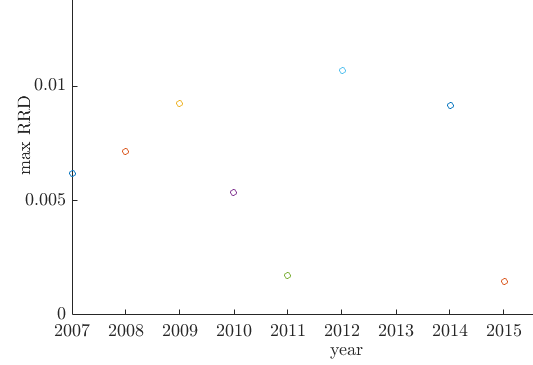

%set figure page
f2 = figure;
set(f2,'Units','Inches','Position',[0.7 12 fw fh]);
set(f2,'PaperPosition',[0 0 fw*2.2 fh*2.2],'PaperSize',[fw fh]);
set(f2,'Color','w','InvertHardcopy','off', 'MenuBar','none');
set(f2,'Resize','off','Toolbar','none');
ax = axes('Units','Inches','position',[axl axb axw axh]);
hold on
for jj = 1:numel(years)
    plot(years(jj),maxRRD(jj),'o')
end
set(gca,'XLim',[min(years),max(years)],'Ylim',[0, max(maxRRD)],TL{:},FS{[1,4]});

%set axis
xlabel('year',TX{:},FS{[1,4]},UN{[1,3]},'Position',[axw/2+ahs/2,-axb/2]);
ylabel('max RRD',TX{:},FS{[1,4]},UN{[1,3]},'Position',[-axl/2,axh/2]);
  

%Save figure
if printfig
  cd(workdirfig);
  % set printing options
  str       = {'maxRRD_year' };
  format    = '-dpng';
  resl      = '-r200';
  rend      = '-opengl';
  figname   = char(strcat(str(1)));
  print(f2,format,resl,rend,figname,'-loose');
end

# How does the lag hour change with active layer thickness

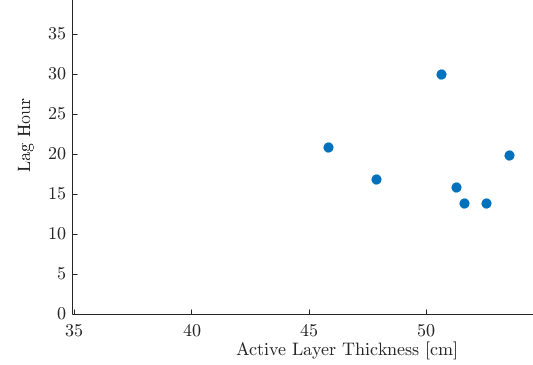

load('/Users/cculha/Documents/git_research/Permafrost_ERRA/Permafrost_ERRA/datERRA/UK/UK_ActiveLayer.mat')
%set figure page
f3 = figure;
set(f3,'Units','Inches','Position',[0.7 12 fw fh]);
set(f3,'PaperPosition',[0 0 fw*2.2 fh*2.2],'PaperSize',[fw fh]);
set(f3,'Color','w','InvertHardcopy','off', 'MenuBar','none');
set(f3,'Resize','off','Toolbar','none');
ax = axes('Units','Inches','position',[axl axb axw axh]);
hold on

AL_index = zeros(size(years_available));
RRD_index = zeros(size(years));

for l = 1: numel(years_available)
        logindx = sum(years == years_available(l))==1; %where the active layer matches RRD
        AL_index(l) = logindx;
end
for l = 1:numel(years)
    logindx = sum(years_available == years(l))==1; %where the active layer matches RRD
    RRD_index(l) = logindx;
end

    plot(meanActiveLayer(logical(AL_index)),maxRRDlgt(logical(RRD_index)),'.','MarkerSize',35)
set(gca,'XLim',[min(meanActiveLayer),max(meanActiveLayer)],'Ylim',[0, max(maxRRDlgt)],TL{:},FS{[1,4]});

%set axis
xlabel('Active Layer Thickness [cm]',TX{:},FS{[1,4]},UN{[1,3]},'Position',[axw/2+ahs/2,-axb/2]);
ylabel('Lag Hour',TX{:},FS{[1,4]},UN{[1,3]},'Position',[-axl/2,axh/2]);
  

%Save figure
if printfig
  cd(workdirfig);
  % set printing options
  str       = {'laghour_ActiveLayer' };
  format    = '-dpng';
  resl      = '-r200';
  rend      = '-opengl';
  figname   = char(strcat(str(1)));
  print(f3,format,resl,rend,figname,'-loose');
end

# How does max RRD change with Active Layer Thickness

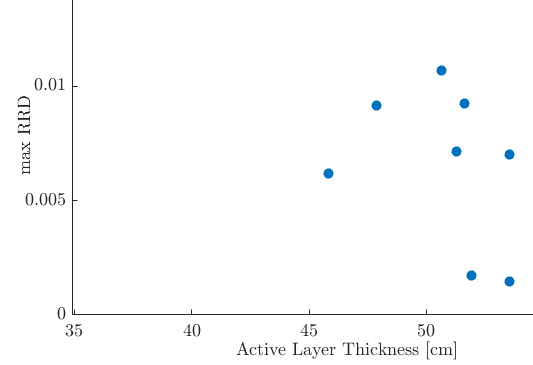

load('/Users/cculha/Documents/git_research/Permafrost_ERRA/Permafrost_ERRA/datERRA/UK/UK_ActiveLayer.mat')
thickingrate = Poly(:,1);
%set figure page
f3 = figure;
set(f3,'Units','Inches','Position',[0.7 12 fw fh]);
set(f3,'PaperPosition',[0 0 fw*2.2 fh*2.2],'PaperSize',[fw fh]);
set(f3,'Color','w','InvertHardcopy','off', 'MenuBar','none');
set(f3,'Resize','off','Toolbar','none');
ax = axes('Units','Inches','position',[axl axb axw axh]);
hold on
AL_index = zeros(size(years_available));
RRD_index = zeros(size(years));

for l = 1: numel(years_available)
        logindx = sum(years == years_available(l))==1; %where the active layer matches RRD
        AL_index(l) = logindx;
end
for l = 1:numel(years)
    logindx = sum(years_available == years(l))==1; %where the active layer matches RRD
    RRD_index(l) = logindx;
end

    plot(meanActiveLayer(logical(AL_index)),maxRRD(logical(RRD_index)),'.','MarkerSize',35)
set(gca,'XLim',[min(meanActiveLayer),max(meanActiveLayer)],'Ylim',[0, max(maxRRD)],TL{:},FS{[1,4]});

%set axis
xlabel('Active Layer Thickness [cm]',TX{:},FS{[1,4]},UN{[1,3]},'Position',[axw/2+ahs/2,-axb/2]);
ylabel('max RRD',TX{:},FS{[1,4]},UN{[1,3]},'Position',[-axl/2,axh/2]);
  

%Save figure
if printfig
  cd(workdirfig);
  % set printing options
  str       = {'mRRD_ActiveLayer' };
  format    = '-dpng';
  resl      = '-r200';
  rend      = '-opengl';
  figname   = char(strcat(str(1)));
  print(f3,format,resl,rend,figname,'-loose');
end

### Combining Active Layer Thickness and Lag Hour with year 

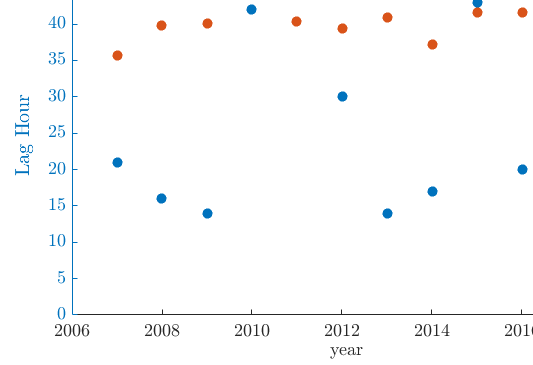

f4 = figure;
set(f4,'Units','Inches','Position',[0.7 12 fw fh]);
set(f4,'PaperPosition',[0 0 fw*2.2 fh*2.2],'PaperSize',[fw fh]);
set(f4,'Color','w','InvertHardcopy','off', 'MenuBar','none');
set(f4,'Resize','off','Toolbar','none');
ax = axes('Units','Inches','position',[axl axb axw axh]);
hold on
yyaxis left
plot(years,maxRRDlgt,'.','MarkerSize',35)
set(gca,'Ylim',[0, max(maxRRDlgt)*1.1],TL{:},FS{[1,4]});
%set axis
ylabel('Lag Hour',TX{:},FS{[1,4]},UN{[1,3]},'Position',[-axl/2,axh/2]);

yyaxis right
plot(years_available(logical(AL_index)),meanActiveLayer(logical(AL_index)),'.','MarkerSize',35);
set(gca,'Ylim',[0, max(meanActiveLayer)*1.1],TL{:},FS{[1,4]});
ylabel('Active Layer Thickness [cm]',TX{:},FS{[1,4]},UN{[1,3]});

xlabel('year',TX{:},FS{[1,4]},UN{[1,3]},'Position',[axw/2+ahs/2,-axb/2]);


%Save figure
if printfig
  cd(workdirfig);
  % set printing options
  str       = {'laghour_ActiveLayer_year' };
  format    = '-dpng';
  resl      = '-r200';
  rend      = '-opengl';
  figname   = char(strcat(str(1)));
  print(f4,format,resl,rend,figname,'-loose');
end

### Combining Active Layer Thickness and RRD max with year

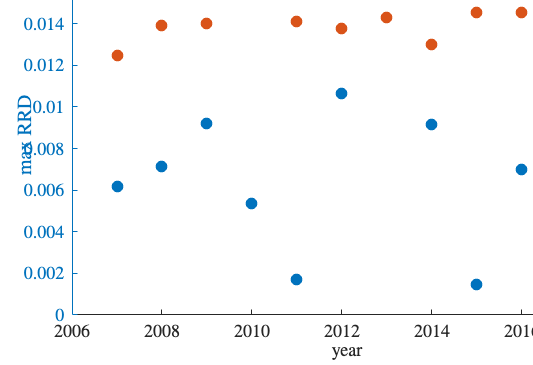

f4 = figure;
set(f4,'Units','Inches','Position',[0.7 12 fw fh]);
set(f4,'PaperPosition',[0 0 fw*2.2 fh*2.2],'PaperSize',[fw fh]);
set(f4,'Color','w','InvertHardcopy','off', 'MenuBar','none');
set(f4,'Resize','off','Toolbar','none');
ax = axes('Units','Inches','position',[axl axb axw axh]);
hold on
yyaxis left
plot(years,maxRRD,'.','MarkerSize',35)
set(gca,'Ylim',[0, max(maxRRD)*1.1],TL{:},FS{[1,4]});
%set axis
ylabel('max RRD',TX{:},FS{[1,4]},UN{[1,3]},'Position',[-axl/2,axh/2]);

yyaxis right
plot(years_available(logical(AL_index)),meanActiveLayer(logical(AL_index)),'.','MarkerSize',35);
set(gca,'Ylim',[0, max(meanActiveLayer)*1.1],TL{:},FS{[1,4]});
ylabel('Active Layer Thickness [cm]',TX{:},FS{[1,4]},UN{[1,3]});

xlabel('year',TX{:},FS{[1,4]},UN{[1,3]},'Position',[axw/2+ahs/2,-axb/2]);


%Save figure
if printfig
  cd(workdirfig);
  % set printing options
  str       = {'maxRRD_ActiveLayer_year' };
  format    = '-dpng';
  resl      = '-r200';
  rend      = '-opengl';
  figname   = char(strcat(str(1)));
  print(f4,format,resl,rend,figname,'-loose');
end

#### How does rate of active layer thickenning compare to maxRRD

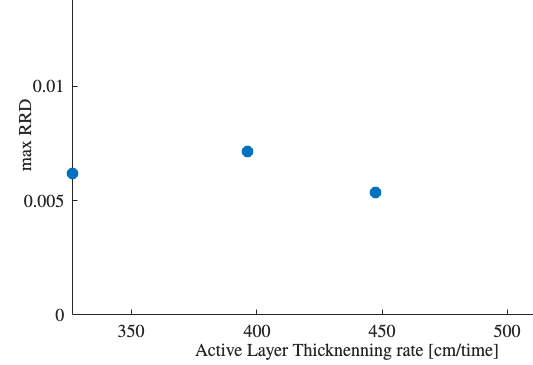


f5 = figure;
set(f5,'Units','Inches','Position',[0.7 12 fw fh]);
set(f5,'PaperPosition',[0 0 fw*2.2 fh*2.2],'PaperSize',[fw fh]);
set(f5,'Color','w','InvertHardcopy','off', 'MenuBar','none');
set(f5,'Resize','off','Toolbar','none');
ax = axes('Units','Inches','position',[axl axb axw axh]);
hold on

plot(thickingrate(logical(AL_index),1),maxRRD(logical(RRD_index)),'.','MarkerSize',35)
set(gca,'XLim',[min(thickingrate(logical(AL_index),1)),max(thickingrate(logical(AL_index),1))],'Ylim',[0, max(maxRRD)],TL{:},FS{[1,4]});

%set axis
xlabel('Active Layer Thicknenning rate [cm/time]',TX{:},FS{[1,4]},UN{[1,3]},'Position',[axw/2+ahs/2,-axb/2]);
ylabel('max RRD',TX{:},FS{[1,4]},UN{[1,3]},'Position',[-axl/2,axh/2]);
  

%Save figure
if printfig
  cd(workdirfig);
  % set printing options
  str       = {'mRRD_ActiveLayerrate' };
  format    = '-dpng';
  resl      = '-r200';
  rend      = '-opengl';
  figname   = char(strcat(str(1)));
  print(f5,format,resl,rend,figname,'-loose');
end

#### How does rate of active layer thickenning compare to Lag Hour

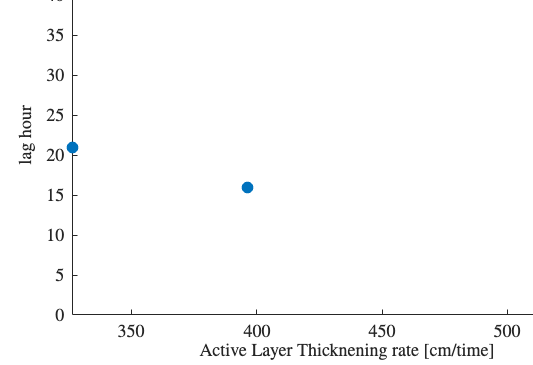


f5 = figure;
set(f5,'Units','Inches','Position',[0.7 12 fw fh]);
set(f5,'PaperPosition',[0 0 fw*2.2 fh*2.2],'PaperSize',[fw fh]);
set(f5,'Color','w','InvertHardcopy','off', 'MenuBar','none');
set(f5,'Resize','off','Toolbar','none');
ax = axes('Units','Inches','position',[axl axb axw axh]);
hold on

plot(thickingrate(logical(AL_index),1),maxRRDlgt(logical(RRD_index)),'.','MarkerSize',35)
set(gca,'XLim',[min(thickingrate(logical(AL_index),1)),max(thickingrate(logical(AL_index),1))],'Ylim',[0, max(maxRRDlgt)],TL{:},FS{[1,4]});

%set axis
xlabel('Active Layer Thicknening rate [cm/time]',TX{:},FS{[1,4]},UN{[1,3]},'Position',[axw/2+ahs/2,-axb/2]);
ylabel('lag hour',TX{:},FS{[1,4]},UN{[1,3]},'Position',[-axl/2,axh/2]);
  

%Save figure
if printfig
  cd(workdirfig);
  % set printing options
  str       = {'laghour_ActiveLayerrate' };
  format    = '-dpng';
  resl      = '-r200';
  rend      = '-opengl';
  figname   = char(strcat(str(1)));
  print(f5,format,resl,rend,figname,'-loose');
end

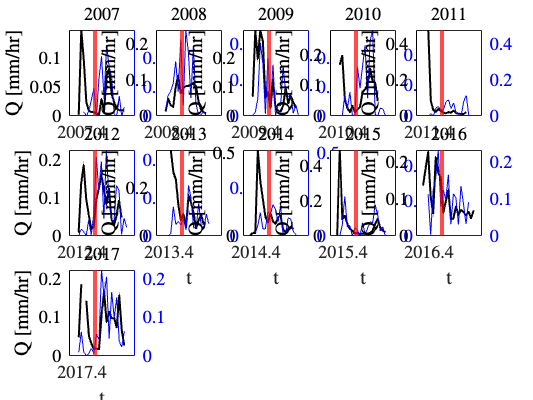

precip = importdata("/Users/cculha/Documents/git_research/Permafrost_ERRA/Permafrost_ERRA/datERRA/UK_ThawingDepth_daily/precipitation.mat");
Precip = precip.P;
days = precip.short_t_cont_num;
Pyears = precip.years;
Pmonths = precip.months;
temp = importdata("/Users/cculha/Documents/git_research/Permafrost_ERRA/Permafrost_ERRA/datERRA/UK_ThawingDepth_daily/airtemperature.mat");
airtemp = temp.airtemp;
discharge = importdata("/Users/cculha/Documents/git_research/Permafrost_ERRA/Permafrost_ERRA/datERRA/UK_ThawingDepth_daily/discharge.mat");
Q = discharge.Q;
f1 = figure;
for l = 1: numel(years)
        logindxYears = (Pyears == years(l));
        logindxMonths = (Pmonths > 5 & Pmonths<9);
        logindxMonthsJ = (Pmonths <= 5 );
        totaldata(l) = sum(logindxYears);
        totalP(l) = nansum(Precip(logindxYears));
        totalT(l) = nanmean(airtemp(logindxYears & logindxMonths));
        totalTJuly(l) = nanmean(airtemp(logindxYears & logindxMonthsJ));
        Q_year = Q(logindxYears);
        P_year = Precip(logindxYears);
        time = days(logindxYears);
     

        % Define the number of hours in a week
            hours_per_week = 168;

        % Reshape the data into a matrix with one week per column
            num_weeks = floor(length(Q_year)/hours_per_week);
            time_matrix = reshape(time(1:num_weeks*hours_per_week), hours_per_week, num_weeks);
            Q_matrix = reshape(Q_year(1:num_weeks*hours_per_week), hours_per_week, num_weeks);
            P_matrix = reshape(P_year(1:num_weeks*hours_per_week), hours_per_week, num_weeks);

        % Calculate the mean of each column to get the weekly averages
            time_weekly_averages = nanmean(time_matrix, 1);
            Q_weekly_averages = nanmean(Q_matrix, 1);
            P_weekly_averages = nanmean(P_matrix, 1);
            maxQ(l) = max(Q_weekly_averages);

        subplot(3, 5, l)
        figtQP_plot_UK_wiMatlab_years(time_weekly_averages,Q_weekly_averages,P_weekly_averages)
        title(years(l),TX{:},FS{[1,4]},UN{[1,3]})
end

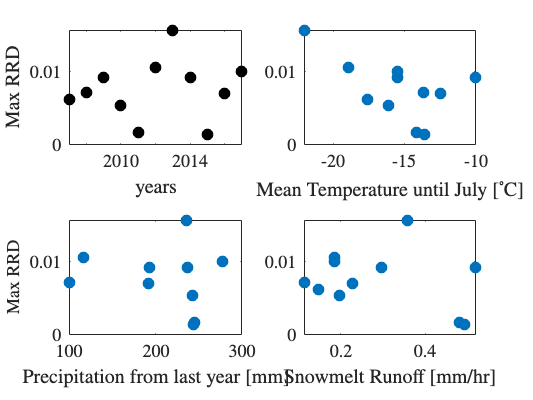

ALT = meanActiveLayer(logical(AL_index));
%enough data?
edat = totaldata./max(totaldata);
totalP_ = totalP(edat>.05);
maxRRD_ = maxRRD(edat>.05);

% Create a 1x4 set of plots
f2 = figure;
subplot(2, 2, 1)
plot(years,maxRRD,'.k','MarkerSize',35)
% title('maxRRD')
ylabel('Max RRD ',TX{:},FS{[1,4]},UN{[1,3]})
xlabel('years',TX{:},FS{[1,4]},UN{[1,3]})
set(gca,TL{:},FS{[1,4]});

subplot(2, 2, 2)
plot(totalTJuly,maxRRD,'.','MarkerSize',35)
xlabel('Mean Temperature until July [$^{\circ}$C]',TX{:},FS{[1,4]},UN{[1,3]})

set(gca,TL{:},FS{[1,4]});

subplot(2, 2, 3)
plot(totalP(1:end-1),maxRRD(2:end),'.','MarkerSize',35)
xlabel('Precipitation from last year [mm]',TX{:},FS{[1,4]},UN{[1,3]})
set(gca,TL{:},FS{[1,4]});
ylabel('Max RRD ',TX{:},FS{[1,4]},UN{[1,3]})

subplot(2, 2, 4)
plot(maxQ,maxRRD,'.','MarkerSize',35)
xlabel('Snowmelt Runoff [mm/hr]',TX{:},FS{[1,4]},UN{[1,3]})
set(gca,TL{:},FS{[1,4]});



% 
% % if printfig
%   cd(workdirfig);
%   % set printing options
%   str       = {'RRD_response' };
%   format    = '-dpng';
%   resl      = '-r200';
%   rend      = '-opengl';
%   figname   = char(strcat(str(1)));
%   print(f2,format,resl,rend,figname,'-loose');
% % end


% subplot(2, 5, 4)
% plot(ALT(1:end-1),maxRRD(2:end),'.','MarkerSize',35)
% title('Active Layer Thickness from last year')

% 
% 
% subplot(2, 3, 5)
% plot(totalT(1:end-1),maxRRD(2:end),'.','MarkerSize',35)
% title('Mean Summer Temperature from last year')



test = [totalP(1:end-1);  ALT(1:end-1); totalT(1:end-1); maxRRD(2:end); maxRRDlgt(2:end); edat(1:end-1)];


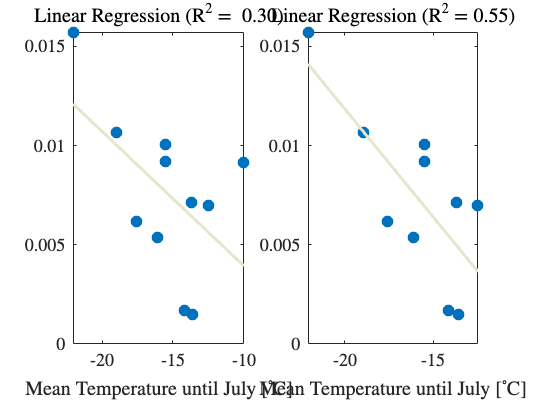

figure
subplot(1, 2, 1)

% Perform linear regression
p = polyfit(totalTJuly, maxRRD, 1);
f = polyval(p, totalTJuly);

% Calculate R-squared value
r2 = 1 - sum((maxRRD - f).^2) / ((length(maxRRD) - 1) * var(maxRRD));


plot(totalTJuly,maxRRD,'.','MarkerSize',35)
hold on
plot(totalTJuly, f, '-y','LineWidth',3,'Color', [.9, .9, 0.8]);
title(sprintf('Linear Regression (R$^2 = $ %.2f)', r2),TX{:},FS{[1,4]},UN{[1,3]});

xlabel('Mean Temperature until July [$^{\circ}$C]',TX{:},FS{[1,4]},UN{[1,3]})
set(gca,TL{:},FS{[1,4]});

subplot(1, 2, 2)

% Perform linear regression
p = polyfit(totalTJuly(years~=2014), maxRRD(years~=2014), 1);
f = polyval(p, totalTJuly(years~=2014));

% Calculate R-squared value
r2 = 1 - sum((maxRRD(years~=2014) - f).^2) / ((length(maxRRD(years~=2014)) - 1) * var(maxRRD(years~=2014)));


plot(totalTJuly(years~=2014),maxRRD(years~=2014),'.','MarkerSize',35)

hold on
plot(totalTJuly(years~=2014), f, '-y','LineWidth',3,'Color', [.9, .9, 0.8]);
title(sprintf('Linear Regression (R$^2 = $%.2f)', r2),TX{:},FS{[1,4]},UN{[1,3]});
xlabel('Mean Temperature until July [$^{\circ}$C]',TX{:},FS{[1,4]},UN{[1,3]})
set(gca,TL{:},FS{[1,4]});